## **Driver test program to check Clothoids library**

**Biarcs**

close all;

% check constructors
x0 = 0; y0 = 2; theta0 = 0;
x1 = 3; y1 = 3; theta1 = pi;
x2 = 5; y2 = 2;

L  = 10;
k0 = 1/3;
dk = 0;

#### Initialize some biarcs

% contruct and initialize a biarc using G1 hermite data
% (points and tangents)
L1 = Biarc( x0, y0, theta0, x1, y1, theta1 );

% Initialize some empty biarcs
L2 = Biarc();
L3 = Biarc();

% contruct the biarc using G1 hermite data
L2.build( x0, y0, theta0, x1, y1, theta1 );
L3.build( x0, y0, theta0, x2, y2, theta1 );

#### Plot some Biarcs

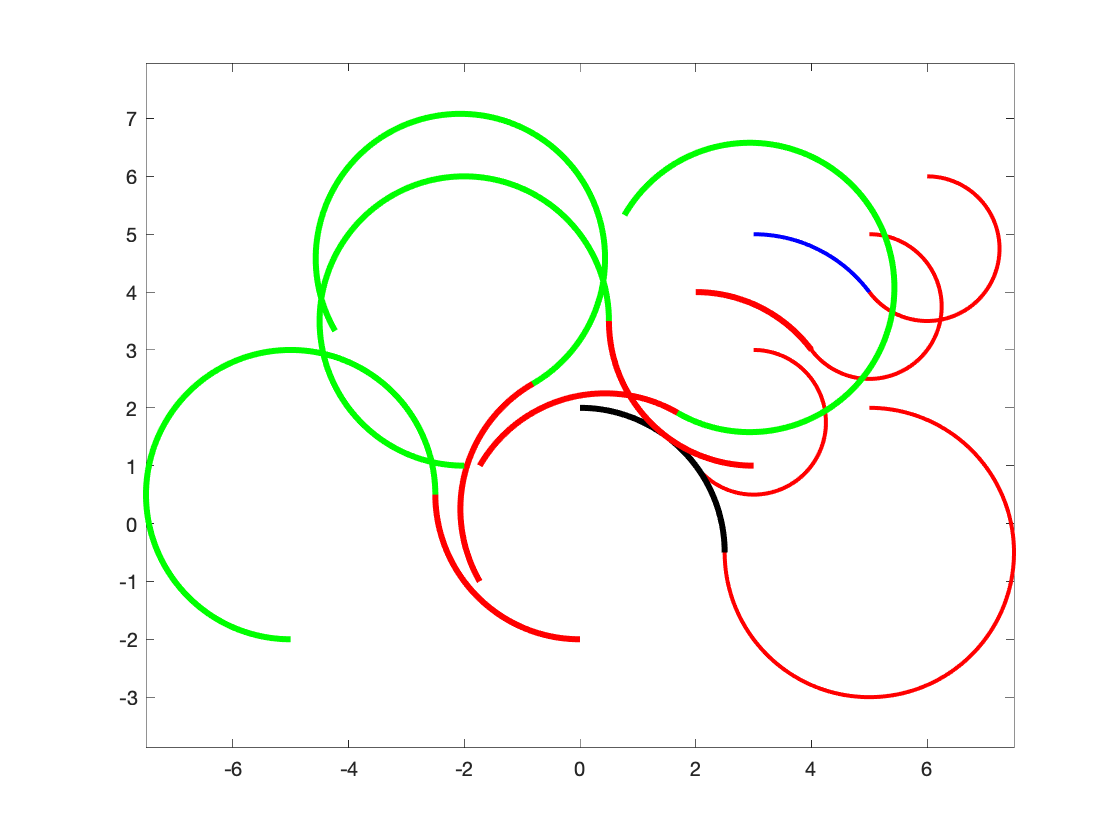

figure();
npts = 1000;
fmt1 = {'Color','red','LineWidth',3};
fmt2 = {'Color','black','LineWidth',3};
fmt3 = {'Color','green','LineWidth',3};
L1.plot(npts,fmt1);
hold on;
L2.plot(npts,fmt1);
L3.plot(npts,fmt2);

L1.translate(1,1);
L1.plot();

L3.rotate(pi/3,0,0);
L3.plot(npts,fmt1,fmt3);

L3.rotate(pi/3,0,0);
L3.plot(npts,fmt1,fmt3);

L3.rotate(pi/3,0,0);
L3.plot(npts,fmt1,fmt3);

L3.translate(3,3);
L3.plot(npts,fmt1,fmt3);
axis equal;

#### Evaluate Biarc at some points

fprintf('L3(1)  = %g\n', L3.eval(1));

L3(1)  = 2.02645
L3(1)  = 1.19735


fprintf('L3''(1) = %g\n', L3.eval_D(1));

L3'(1) = -0.921061
L3'(1) = 0.389418


fprintf('L3''''(1) = %g\n', L3.eval_DD(1));

L3''(1) = 0.155767
L3''(1) = 0.368424


fprintf('L3''''''(1) = %g\n', L3.eval_DDD(1));

L3'''(1) = 0.14737
L3'''(1) = -0.0623069


fprintf('L3 initial [x,y,theta] = [%g,%g,%g]\n', ...
         L3.xBegin(),L3.yBegin(),L3.thetaBegin());

L3 initial [x,y,theta] = [3,1,3.14159]


L3.length()

ans =   15.707963267948966
